## Dataset

### Partial dataset

The dataset is collected from a **[wind turbine specs]** 2MW wind turbine high-speed shaft driven by a 20-tooth pinion gear [1]. A **[data sampling]** vibration signal of 6 seconds was acquired each day for 50 consecutive days (there are 2 measurements on March 17, which are treated as two days in this example). An inner race fault developed and caused the failure of the bearing across the 50-day period. 

A compact version of the dataset is available in the toolbox. To use the compact dataset, copy the dataset to the current folder and enable its write permission.

The measurement time step for the compact dataset is 5 days.

The results in this example are generated from the full dataset. It is highly recommended to download the full dataset to run this example. Results generated from the compact dataset might not be meaningful.

## Data Import

Create a `fileEnsembleDatastore` of the wind turbine data. The data contains a **vibration signal** and a **tachometer signal**. The `fileEnsembleDatastore` will parse the file name and extract the date information as `IndependentVariables`. See the helper functions in the supporting files for more details.

currentfolder = pwd

currentfolder = 'C:\Users\bensi\Documents\Coding\Project\Pole-IA-Predictive-Maintenance\Main_Files\code'

hsbearing = fileEnsembleDatastore(...
    fullfile('.', 'Data'), ...
    '.mat');
hsbearing.DataVariables = ["vibration", "tach"]

hsbearing =   fileEnsembleDatastore with properties:

                 ReadFcn: []
        WriteToMemberFcn: []
           DataVariables: [2×1 string]
    IndependentVariables: [0×0 string]
      ConditionVariables: [0×0 string]
       SelectedVariables: [0×0 string]
                ReadSize: 1
              NumMembers: 50
          LastMemberRead: [0×0 string]
                   Files: [50×1 string]


N_days = hsbearing.NumMembers;
hsbearing.IndependentVariables = "Date"

hsbearing =   fileEnsembleDatastore with properties:

                 ReadFcn: []
        WriteToMemberFcn: []
           DataVariables: [2×1 string]
    IndependentVariables: "Date"
      ConditionVariables: [0×0 string]
       SelectedVariables: [0×0 string]
                ReadSize: 1
              NumMembers: 50
          LastMemberRead: [0×0 string]
                   Files: [50×1 string]


hsbearing.SelectedVariables = ["Date", "vibration", "tach"]

hsbearing =   fileEnsembleDatastore with properties:

                 ReadFcn: []
        WriteToMemberFcn: []
           DataVariables: [2×1 string]
    IndependentVariables: "Date"
      ConditionVariables: [0×0 string]
       SelectedVariables: [3×1 string]
                ReadSize: 1
              NumMembers: 50
          LastMemberRead: [0×0 string]
                   Files: [50×1 string]


hsbearing.ReadFcn = @helperReadData;
hsbearing.WriteToMemberFcn = @helperWriteToHSBearing;
tall(hsbearing)

ans =

  M×3 tall table

            Date                vibration             tach      
    ____________________    _________________    _______________

    07-Mar-2013 01:57:46    {585936×1 double}    {2446×1 double}
    08-Mar-2013 02:34:21    {585936×1 double}    {2411×1 double}
    09-Mar-2013 02:33:43    {585936×1 double}    {2465×1 double}
    10-Mar-2013 03:01:02    {585936×1 double}    {2461×1 double}
    11-Mar-2013 03:00:24    {585936×1 double}    {2506×1 double}
    12-Mar-2013 06:17:10    {585936×1 double}    {2447×1 double}
    13-Mar-2013 06:34:04    {585936×1 double}    {2438×1 double}
    14-Mar-2013 06:50:41    {585936×1 double}    {2390×1 double}
             :                      :                   :
             :                      :    

Sample rate of vibration signal is 97656 Hz. 

fs = 97656; % Hz

## Data Exploration

This section explores the data in both time domain and frequency domain and seeks inspiration of what features to extract for prognosis purposes.

First visualize the vibration signals in the time domain. In this dataset, there are 50 vibration signals of 6 seconds measured in 50 consecutive days. Now plot the 50 vibration signals one after each other.

reset(hsbearing)
tstart = 0;
figure
hold on
currentfolder = pwd

currentfolder = 'C:\Users\bensi\Documents\Coding\Project\Pole-IA-Predictive-Maintenance\Main_Files\code'

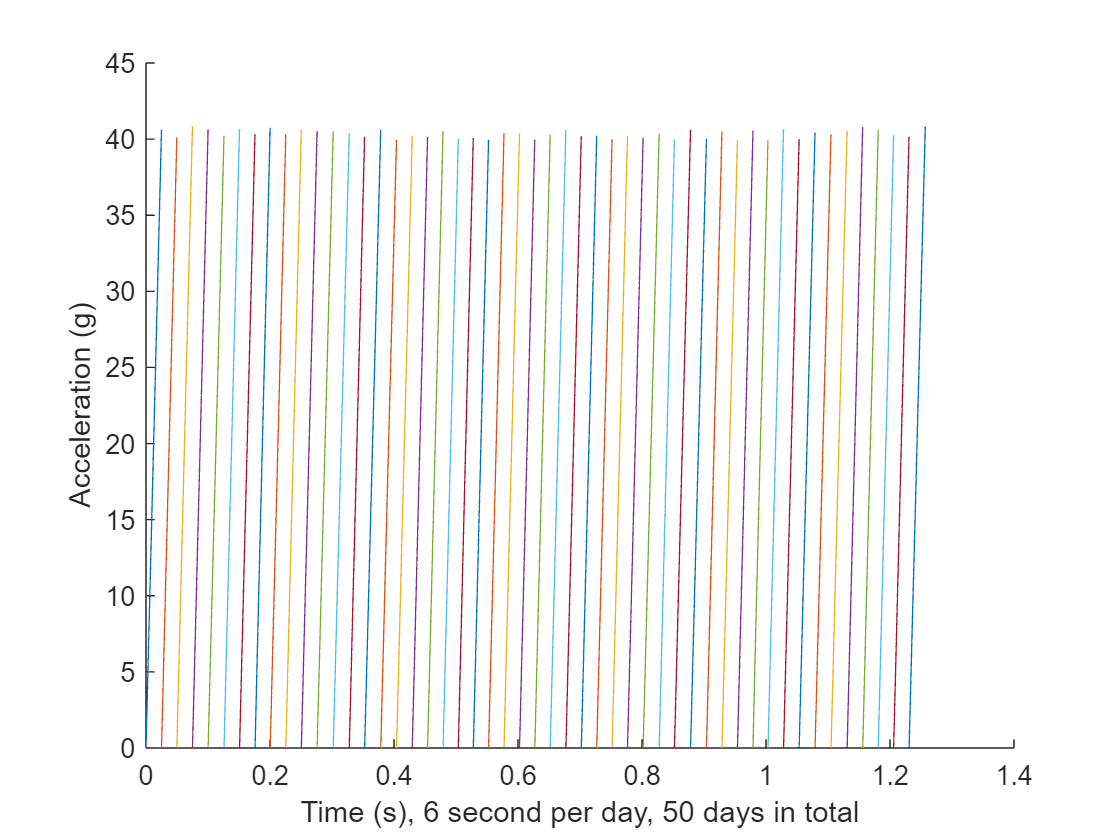

while hasdata(hsbearing)
    data = read(hsbearing);
    v = data.tach{1};
    t = tstart + (1:length(v))/fs;
    % Downsample the signal to reduce memory usage
    plot(t(1:10:end), v(1:10:end))
    tstart = t(end);
end
hold off
xlabel('Time (s), 6 second per day, 50 days in total')
ylabel('Acceleration (g)')

The vibration signals in time domain reveals an increasing trend of the signal impulsiveness. Indicators quantifying the impulsiveness of the signal, such as kurtosis, peak-to-peak value, crest factors *etc.*, are potential prognostic features for this wind turbine bearing dataset [2]. 

On the other hand, spectral kurtosis is considered powerful tool for wind turbine prognosis in frequency domain [3]. To visualize the spectral kurtosis changes along time, plot the spectral kurtosis values as a function of frequency and the measurement day.

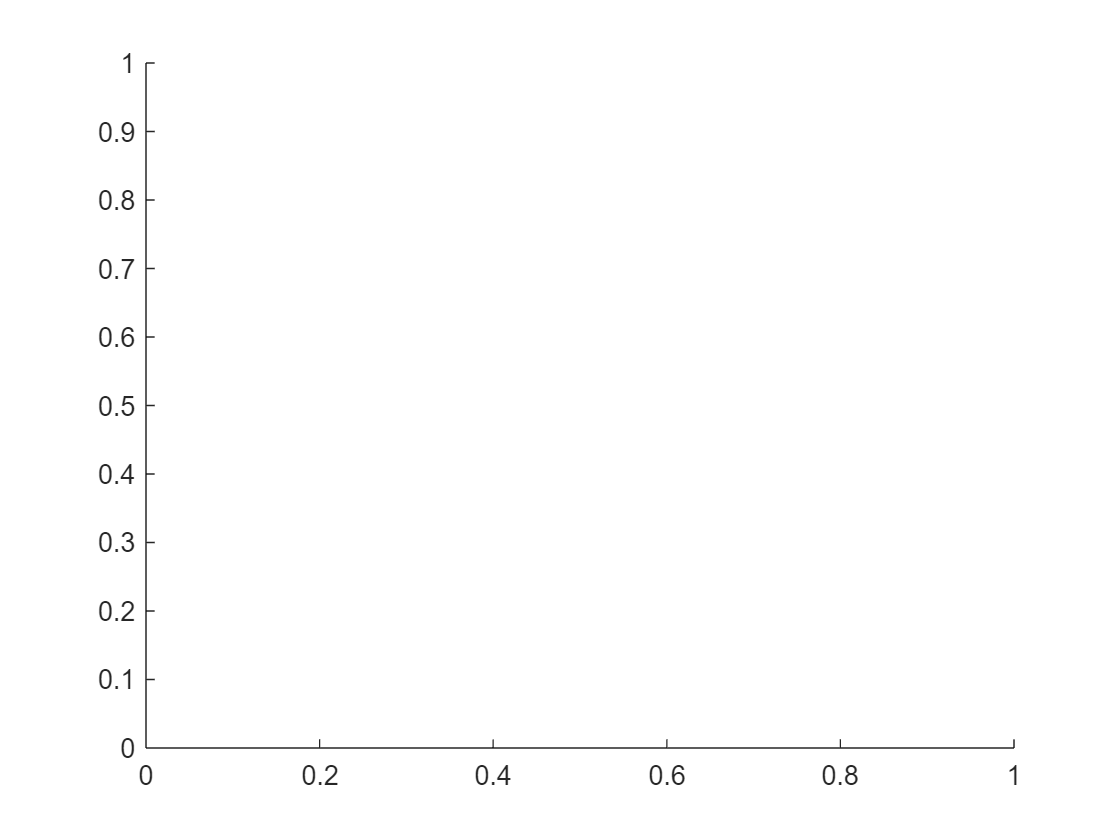

hsbearing.DataVariables = ["vibration", "tach", "SpectralKurtosis"];
colors = parula(50);
figure
hold on

reset(hsbearing)
day = 1;
currentfolder = pwd

currentfolder = 'C:\Users\bensi\Documents\Coding\Project\Pole-IA-Predictive-Maintenance\Main_Files\code'

Sk_max = zeros(1, N_days);
F_max = zeros(1, N_days);
Sk_mean = zeros(1, N_days);
Sk_sd = zeros(1, N_days);

while hasdata(hsbearing)
    data = read(hsbearing);
    data2add = table;
    % Get vibration signal and measurement date
    
    v = data.vibration{1};
    %[speed, acceleration] = tach_deriv(v);

    % Compute spectral kurtosis with window size = 128
    wc = 128;
    [SK, F] = pkurtosis(v, fs, wc);
    data2add.SpectralKurtosis = {table(F, SK)};
    days = linspace(
    % Plot the spectral kurtosis
    plot(day*ones(size(F)), SK, 'Color', colors(day*5, :))

    %track dominant frequency behavior
    [Sk_m, Sk_i] = max(SK);
    Sk_max(day) = Sk_m;
    if F(Sk_i) >= 1.5*median(SK)
        F_max(day) = F(Sk_i);
    else
        F_max(day) = 0;
    end

    SK_mean = mean(SK);
    Sk_mean(day) = SK_mean;
    SK_SD = std(SK);
    Sk_sd(day) = SK_SD;

    % Write spectral kurtosis values
    writeToLastMemberRead(hsbearing, data2add);
    
    % Increment the number of days
    day = day + 1;
end

Error using plot3
Not enough input arguments.

hold off
xlabel('Frequency (Hz)')
ylabel('Time (day)')
zlabel('Spectral Kurtosis')
grid on
view(-45, 30)
cbar = colorbar;
ylabel(cbar, 'Fault Severity (0 - healthy, 1 - faulty)')


N_graph = 5
subplot(1, N_graph, 1);
days = linspace(1, N_days, N_days);
plot(days, F_max);
title('Dominant Frequency')
xlabel('Time (day)')
ylabel('Hz')
%
subplot(1, N_graph, 2);
plot(days, Sk_max);
title('Max')
xlabel('Time (day)') 
ylabel('SK')
%
subplot(1, N_graph, 3);
plot(days, Sk_max/Sk_max(1));
title('Normalised Max')
xlabel('Time (day)')
ylabel('SK')
%
subplot(1, N_graph, 4);
plot(days, Sk_mean);
title('Mean')
xlabel('Time (day)')
ylabel('SK')
%
subplot(1, N_graph, 5);
plot(days, Sk_sd);
title('Standard Deviation')
xlabel('Time (day)')
ylabel('SK')
sgtitle('Spectral Kurtosis Properties of Vibration')

Fault Severity indicated in colorbar is the measurement date normalized into 0 to 1 scale. It is observed that the spectral kurtosis value around 10 kHz gradually increases as the machine condition degrades. Statistical features of the spectral kurtosis, su

hsbearing.reset()

ch as mean, standard deviation *etc.*, will be potential indicators of the bearing degradation [3].

## References

[1] Bechhoefer, Eric, Brandon Van Hecke, and David He. "Processing for improved spectral analysis." *Annual Conference of the Prognostics and Health Management Society, New Orleans, LA, Oct*. 2013.

[2] Ali, Jaouher Ben, et al. "Online automatic diagnosis of wind turbine bearings progressive degradations under real experimental conditions based on unsupervised machine learning." *Applied Acoustics* 132 (2018): 167-181.

[3] Saidi, Lotfi, et al. "Wind turbine high-speed shaft bearings health prognosis through a spectral Kurtosis-derived indices and SVR." *Applied Acoustics* 120 (2017): 1-8.

*Copyright 2022 The MathWorks, Inc.*